if ~(exist("EW","var")&&isa(EW.Object,"Gbec.ExperimentWorker")&&isvalid(EW.Object))
	EW=MATLAB.Lang.Owner(Gbec.ExperimentWorker);
end

通用行为实验控制器v5.0.0 by 张天夫


# 在下方输入会话设置

串口号

EW.SerialInitialize("COM5");

选择要运行的会话

EW.SessionUID=Gbec.UID.Session_LightAir;
SessionName=char(EW.SessionUID);

设置实验基本信息

EW.Mouse='FakeMouse';
EW.DateTime=datetime;
Filename=sprintf('D:\\张天夫\\%s.%s.%s',EW.Mouse,char(EW.DateTime,'yyyyMMddHHmm'),SessionName(9:end));
EW.SavePath=strcat(Filename,'.行为.UniExp.mat');

会话结束后是否自动关闭串口

EW.ShutDownSerialAfterSession=true;

如果使用喵提醒服务，输入事件ID；如果不使用，设为空字符串""

EW.EndMiaoCode="";

视频拍摄设置（如果不拍视频，将if条件设为false即可）。如果不清楚该怎么设置，先使用 Image Acquisition App 生成代码，得到所需参数。

if true
	VideoArguments={'winvideo',2,'MJPG_320x240'};%选择正确的设备和格式
	try
		EW.VideoInput=videoinput(VideoArguments{:});
	catch
		imaqreset
		EW.VideoInput=videoinput(VideoArguments{:});
	end
	EW.VideoInput.DiskLogger=VideoWriter(strcat(Filename,'.mp4'),'MPEG-4'); %选择视频保存路径
	EW.VideoInput.TriggerRepeat=Inf;%一般不应修改，除非提前知道回合数
	EW.VideoInput.FramesPerTrigger=200; %拍摄帧数，通常大于回合关键部分的时长×帧速率。如果全程拍摄，设为Inf
	EW.VideoInput.LoggingMode='disk'; %记录模式，一般无需修改。如果不写出到磁盘，请设为'memory'。
	triggerconfig(EW.VideoInput,'manual');%如果全程拍摄，设为immediate；设为manual则只拍回合开始后一段时间
else
    EW.VideoInput=[];
end

# 然后运行脚本，在命令行窗口中执行交互

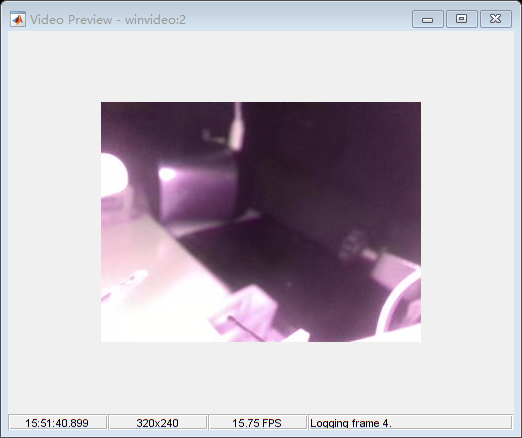

会话开始


EW.StartSession;

return;

# 实时控制命令

暂停会话

EW.PauseSession;

会话暂停


继续会话

EW.ContinueSession;

会话继续


放弃会话

EW.AbortSession;

会话已放弃


错误使用 Gbec/ExperimentWorker/SaveInformation
输入参数太多。

出错 Gbec.ExperimentWorker/AbortAndSave (第 71 行)
					EW.SaveInformation(EW.SessionUID);

出错 Gbec.ExperimentWorker/AbortSession (

获取信息

EW.GetInformation

ans = 包含以下字段的 struct :
               UID: "Session_LAWLwAw"
            Random: 1
    DistinctTrials: {5×1 cell}
         NumTrials: [20 20 20 20 20]


查询状态

EW.PeekState;

    State_SessionRunning



关闭串口

clearvars EW;